# Exercise 2.2 - Convolution

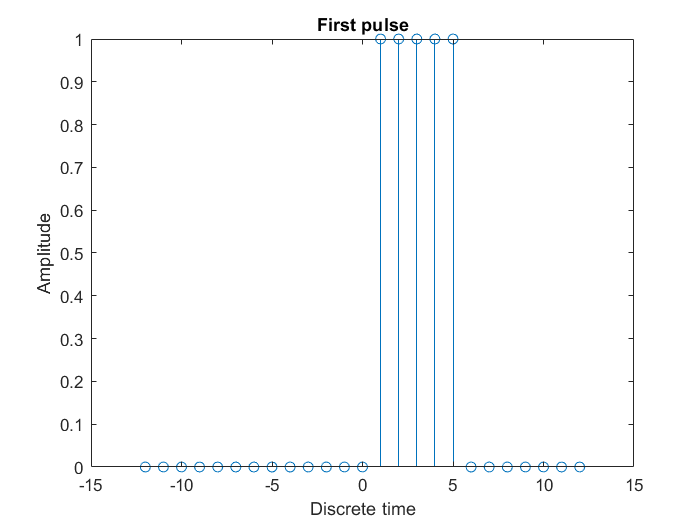

% Compute and plot the convolution between two rectangular pulses of different duration 
% and amplitude defined between n = -12 and n = 12.
%
% x1[n], rectangular pulse with 5 samples and centered around n = 3.
% x2[n], rectangular pulse of amplitude 2, with 7 samples and centered around n = -2.

% Define the discrete time interval.
nx = -12 : 12;

% Set up the first pulse.
x1 = zeros(1, 25);
startx1 = find(nx == 1);
endx1 = find(nx == 5);
x1(startx1 : endx1) = 1;

% Let's plot it to make sure it has enough samples and its center is in the
% right place.
stem(nx, x1);
title("First pulse"), xlabel('Discrete time'), ylabel('Amplitude')

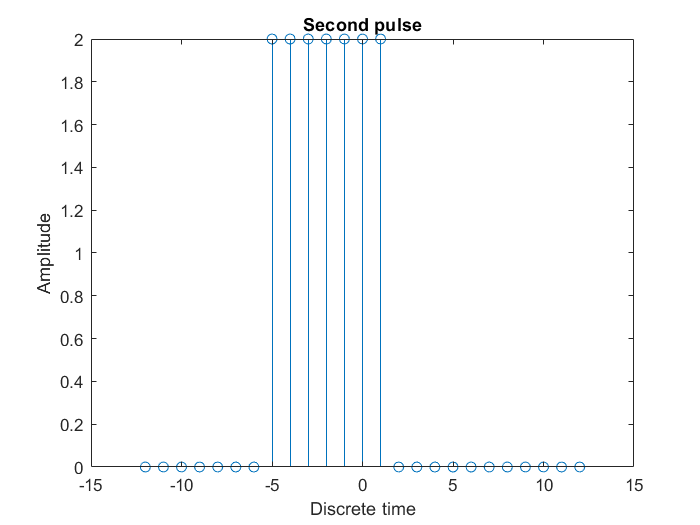


% Set up the second pulse.
x2 = zeros(1, 25);
startx2 = find(nx == -5);
endx2 = find(nx == 1);
x2(startx2 : endx2) = 2;

% Again, let's double check by plotting it.
stem(nx, x2);
title("Second pulse"), xlabel('Discrete time'), ylabel('Amplitude')

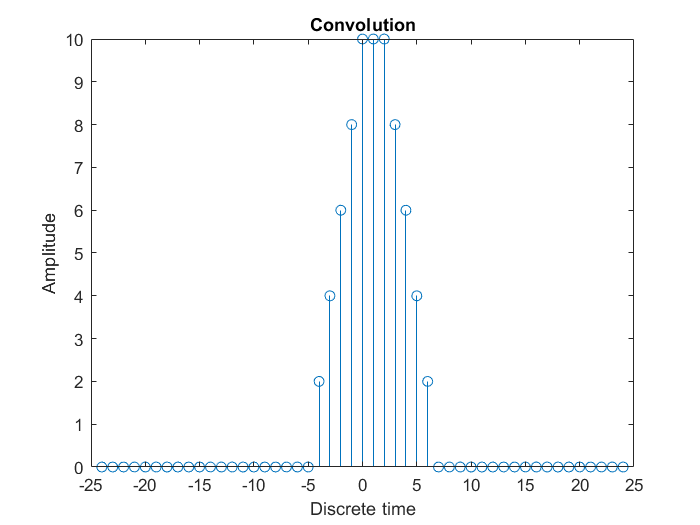


% Compute the convolution between the two signals.
y = conv(x1, x2);

% Let's plot the result.
ny = - 24 : 24;
stem(ny, y);
title("Convolution"), xlabel('Discrete time'), ylabel('Amplitude')